% Test of Hyper geometric

%mhg(20,2,[0.1,0.2],[0.3,0.4],[0.5 0.6 0.7])      2F2(2)(0.1,0.2; 0.3,0.4; diag(0.5,0.6,0.7)).
%mhg(20,1,[ ],[0.1],[0.2 0.3 0.4],[0.5 0.6 0.7])  0F1(1)(0.1; diag(0.2,0.3,0.4),diag(0.5,0.6,0.7)).
%mhg([20 4],1,[0.8],[0.1],[0.2 0.3 0.4])          1F1(1)(0.8;0.1; diag(0.2,0.3,0.4))
%mhg([10 4 4 3 1],1,[0.8],[0.1],[0.2 0.3 0.4])    1F1(1)(0.8;0.1; diag(0.2,0.3,0.4))


c =     1.0000   -6.6667   26.6667  -76.1905  169.3122 -307.8403  473.6005 -631.4673  742.9027 -782.0028  744.7646 -647.6214  518.0971 -383.7756  264.6729 -170.7567  103.4889  -59.1365   31.9657  -16.3927    7.9964   -3.7193    1.6530   -0.7034    0.2871   -0.1126    0.0425   -0.0154    0.0054   -0.0018    0.0006   -0.0002    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000


out = 0.3332

%mhg([],1,[0.8],[0.1],[0.2 0.3 0.4]) 
%returns 13.4183, which is an approximation to
% 1F1(1) (0.8;0.1; diag(0.2,0.3,0.4))


clc; clear;
M = eye(3,3);
Z = [-20 0 0]';
B = BinghamDistribution(Z, M);

default
mhg


B.integral()

ans = 0.9984

B.plot(200, 0);

### Evaluating mgh approximation

clear; clc; clf; rng(5); format long

H = [0, 40, 60];
dim = 3;
i = 100

i =    100


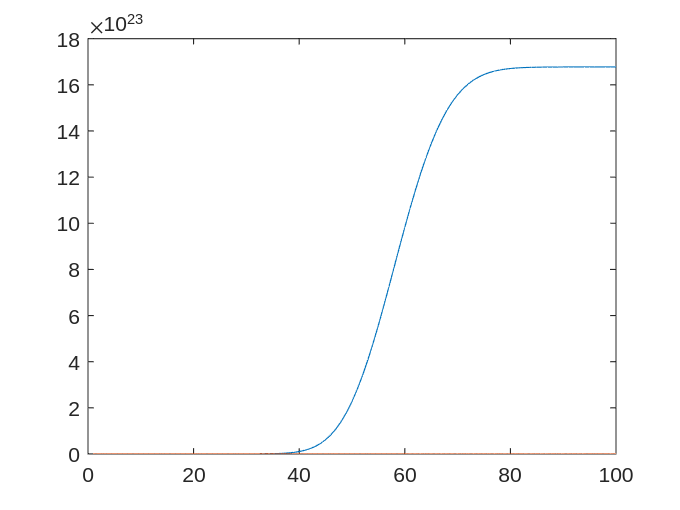


prec = zeros(1,i);
lprec = zeros(1,i);

for m = 5:i
    tic;
    [s,c] = mhg(m, 2, 0.5, dim/2, H);
    prec(m) = s;
end

for m = 5:i
    tic;
    ls = logmhg(m, 2, 0.5, dim/2, H);
    lprec(m) = toc;
end

plot(prec)
hold on
plot(lprec)


%s
%exp(ls)

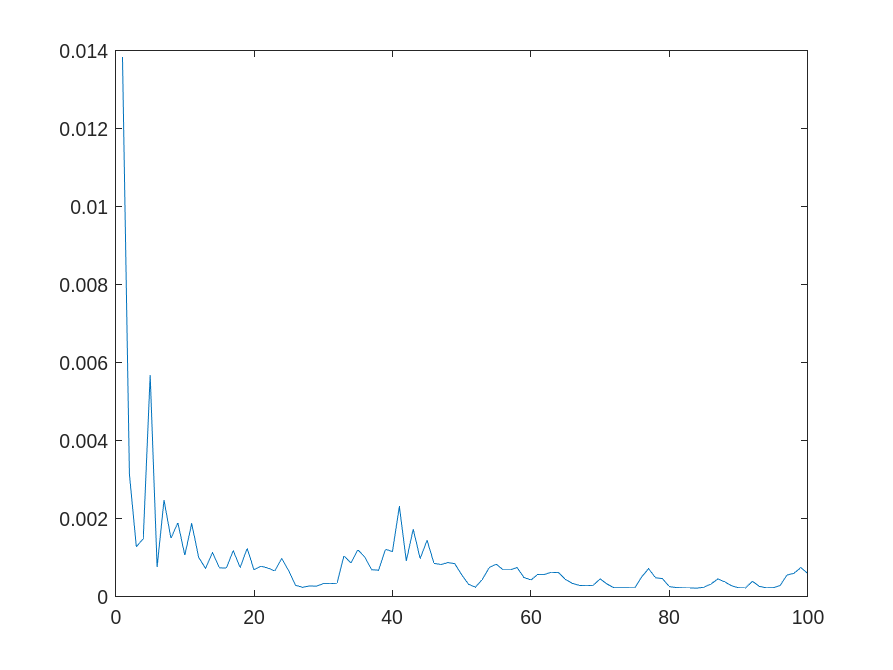

%dimension Time complexity
p = 100;
conv = zeros(1,p);
Zt = sort(randi([1 50],1,p));

for dim = 1:p
    tic
    [s,c] = mhg(20, 2, 0.5, p/2, Zt);
    conv(dim) = toc;
end
%semilogy(conv)
plot(conv)

%increased precission time complexity
clear;
acc = 80;
atp = 10

atp = 10

prec = zeros(1,acc);
Zt = sort(randi([1 50],1,atp));

Zt =      3     5     7    13    20    21    29    40    48    48


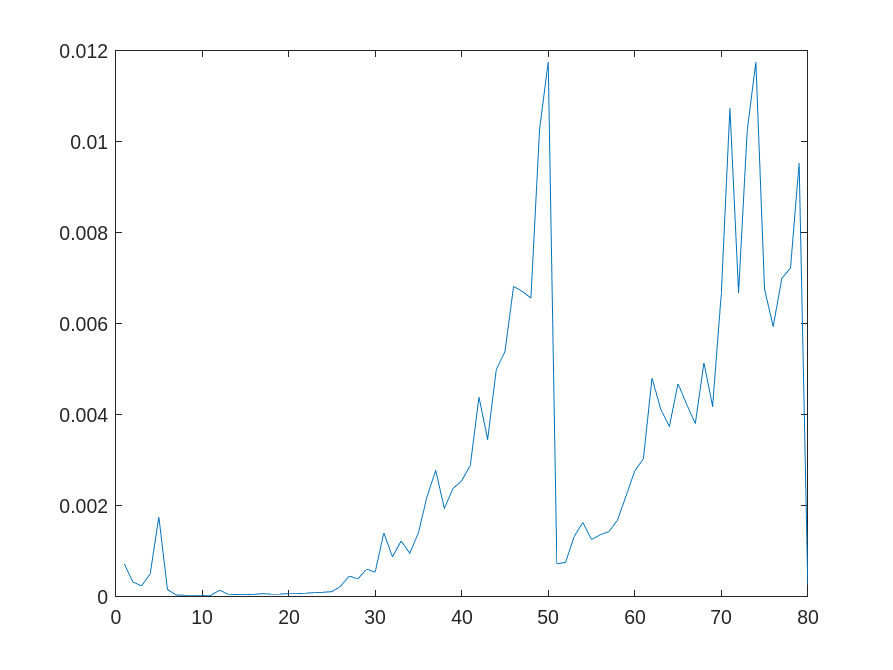


for m = 1:acc
    tic
    [s,c] = mhg(m, 2, 0.5, atp/2, Zt);
    prec(m) = toc;
end
%semilogy(conv)
plot(prec)

%Convergence value as a function of precision
clear;
acc = 60;
atp = 30

atp = 30

prec = zeros(1,acc);
logprec = zeros(1,acc);

Zt = sort(randi([-40 -10],1,atp))

Zt =    -40   -39   -37   -37   -36   -34   -32   -30   -30   -29   -28   -26   -25   -25   -25   -21   -20   -19   -19   -19   -18   -18   -17   -16   -16   -13   -13   -12   -12   -10


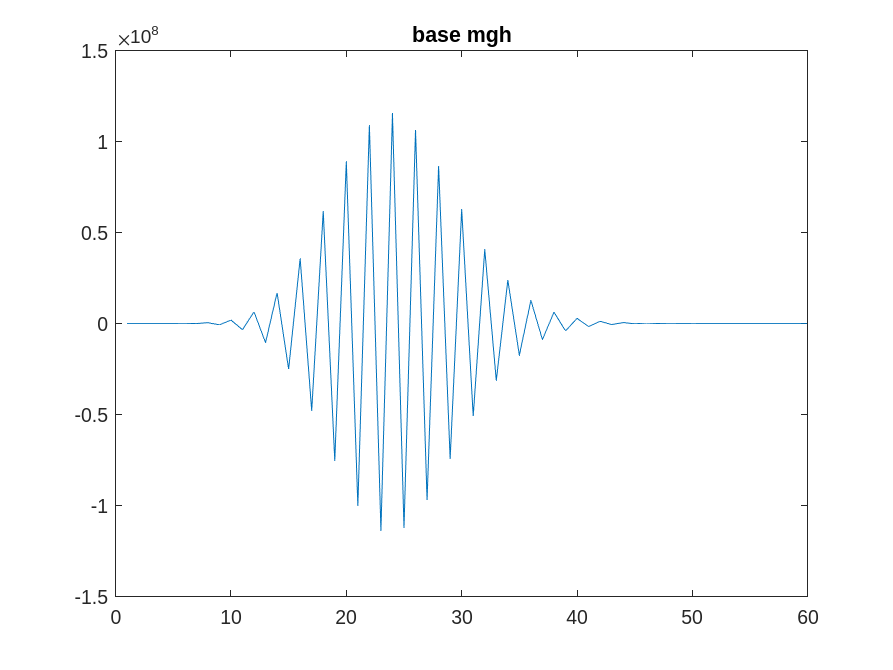

for m = 1:acc
    [s,c] = mhg(m, 2, 0.5, atp/2, Zt);
    %g = logmhg(m, 2, 0.5, atp/2, Zt);
    prec(m) = s;
    %logprec(m)= g;
end
%semilogy(conv)
%subplot(3,1,1);
plot(prec)
title('base mgh')


%subplot(3,1,2); 
%plot(exp(logprec))
%title("exp(log mgh)")
%subplot(3,1,3);
%plot(logprec)
%title("log mgh")

% Integral evaluation
clear

p = 3;
x = randn(1,p)';
x = x ./ norm(x); % Normalization
x'*x

ans = 1

%Z = diag(sort(randi([-10 10],1,p))) % random diagonal matrix ascending diagonal values

Z =     -6     0     0
     0     0     0
     0     0     1


Z = [-60]

M = eye(p,p);
A = M*Z*M';

% Check Trace
sum(x.*A*x)

ans = -2.4107

t = trace(A*(x*x'))

t = -2.4107

% This only hold under the assumption of orthogonal and diagonal matrix

switch p
    case 2
        surfA = 2*pi;
    case 3
        surfA = 4*pi;
    case 4

end

pdf = @(xvar) 1/(surfA*mhg(100, 2, 0.5, size(xvar,1)/2,eig(Z))) * exp(sum(xvar.*(Z*xvar)));
prob = pdf(x)

prob = 0.0118

integrationBoundaries = [zeros(size(x,1)-1,1), [2*pi;pi*ones(size(x,1)-2,1)]];
switch p
    case 2
        f = @(phi) pdf([cos(phi); sin(phi)]);
        i = integral(f,integrationBoundaries(1,1), integrationBoundaries(1,2), 'AbsTol', 0.01)
        
    case 3
        
        r=1;
        f = @(xvar) pdf(xvar);
        % spherical coordinates
        fangles = @(phi1,phi2) f([ ...
                    r.*sin(phi1).*sin(phi2); ...
                    r.*cos(phi1).*sin(phi2); ...
                    r.*cos(phi2); ...
                    ]);
        
        g = @(phi1,phi2) reshape(fangles(phi1(:)',phi2(:)').*sin(phi2(:)'),size(phi1)); % volume correcting term
    
        i = integral2(g, integrationBoundaries(1,1), integrationBoundaries(1,2),...
                        integrationBoundaries(2,1), integrationBoundaries(2,2), 'AbsTol', 1e-3, 'RelTol', 1e-3)

    case 4   
        r=1;

        % hyperspherical coordinates
        fangles = @(phi1,phi2,phi3) pdf([ ...
        r.*sin(phi1).*sin(phi2).*sin(phi3); ...
        r.*cos(phi1).*sin(phi2).*sin(phi3); ...
        r.*cos(phi2).*sin(phi3); ...
        r.*cos(phi3)
        ]);

        g = @(phi1,phi2,phi3) fangles(phi1,phi2,phi3) .* sin(phi2).*(sin(phi3)).^2; % volume correcting term
        ga = @(phi1,phi2,phi3) reshape(g(phi1(:)', phi2(:)', phi3(:)'), size(phi1));

        i = integral3(ga, integrationBoundaries(1,1), integrationBoundaries(1,2),...
            integrationBoundaries(2,1), integrationBoundaries(2,2),...
            integrationBoundaries(3,1), integrationBoundaries(3,2), 'AbsTol', 1e-3, 'RelTol', 1e-3);
end

i = 1.0000